clear

syms theta1 theta2 theta3 theta4 theta5 theta6

A = [  0     -1     0.15
      200     0      0
     theta3 theta4 theta5 ];
B = [  0
       0
     theta6];
C = [0 1 0];
graybox = struct('A',A,'B',B,'C',C);
clear theta1 theta2 theta3 theta4 theta5 theta6

A = [-19.4230192310286  5.33689098338979    3.49995019807661
     -12.1311290167373 -0.602045011451299 -11.4818883114291
      16.3130278947638 14.8960978823999    -4.97493575752010];
B = [-1.72337203677241
     -0.644436459399537
      1.72830662854464 ];
C = [10.8506957537365 -6.92573694290204 8.23730466120267];
blackbox = ss(A,B,C,0);
clear A B C

sol = gray3sid(blackbox, graybox, 'Method','similarityTransform');
disp(sol.parameters.')

$$\left(\begin{array}{cccc} \theta_{3} & \theta_{4} & \theta_{5} & \theta_{6} \end{array}\right)$$

disp(sol.parameter_values.')

 -600.0000  -10.0000  -25.0000 -100.0000



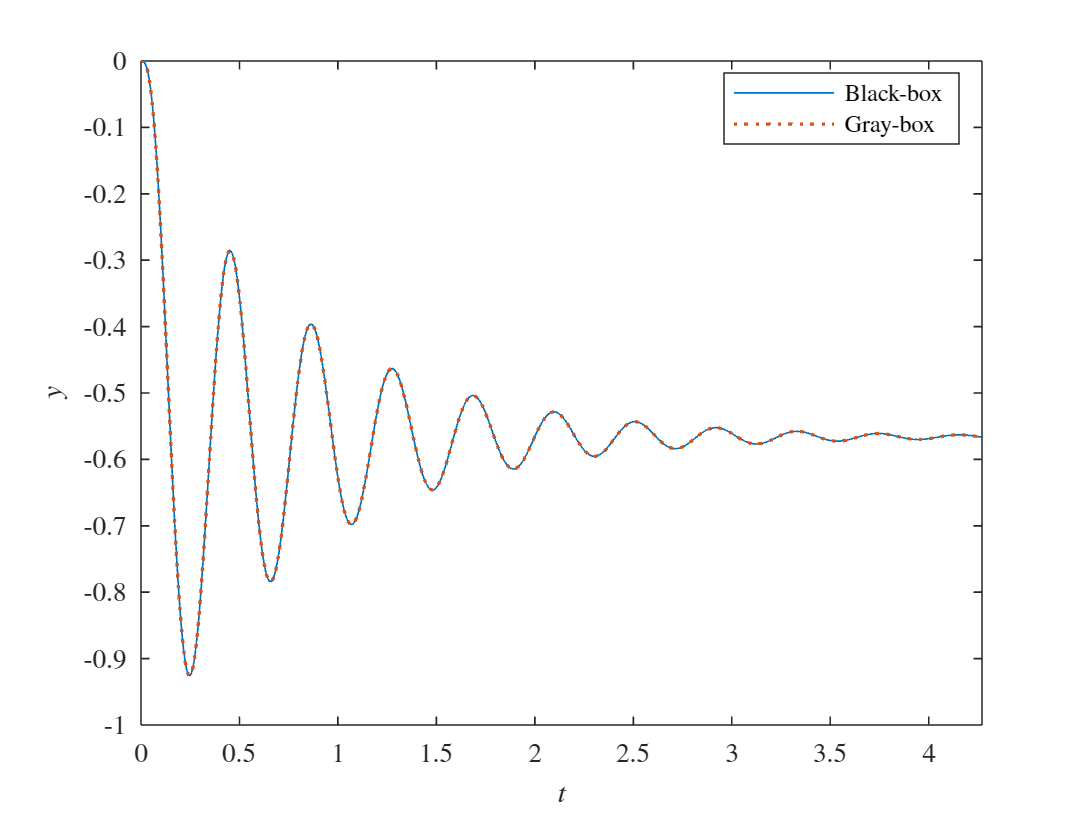


figure
hold on
[y,t] = step(blackbox);
plot(t, y, '-', 'DisplayName','Black-box', 'LineWidth',0.5)
[y,t] = step(sol.sys);
plot(t, y, ':', 'DisplayName','Gray-box',  'LineWidth',1)
legend('Location','best')
xlabel('$t$')
ylabel('$y$')
xlim([min(t) max(t)])
box on

clear

syms theta1 theta2 theta3

A = [1 theta1
     1 -3];
B = [theta2
       1   ];
C = [1 0];
graybox = struct('A',A,'B',B,'C',C);
clear theta1 theta2 theta3

A = [177.776963379520  -496.711190701046
      64.3476596331393 -179.776963379520];
B = [3.72290476694050
     1.33660669226990];
C = [14.3600000000000  -37.7530000000000];
blackbox = ss(A,B,C,0);
clear A B C

sol = gray3sid(blackbox, graybox, 'Method','DCP');

DCP method stopped because the size of the current step is less than StepTolerance


disp(sol.parameters.')

$$\left(\begin{array}{cc} \theta_{1} & \theta_{2} \end{array}\right)$$

disp(sol.parameter_values.')

   -5.0000    3.0000



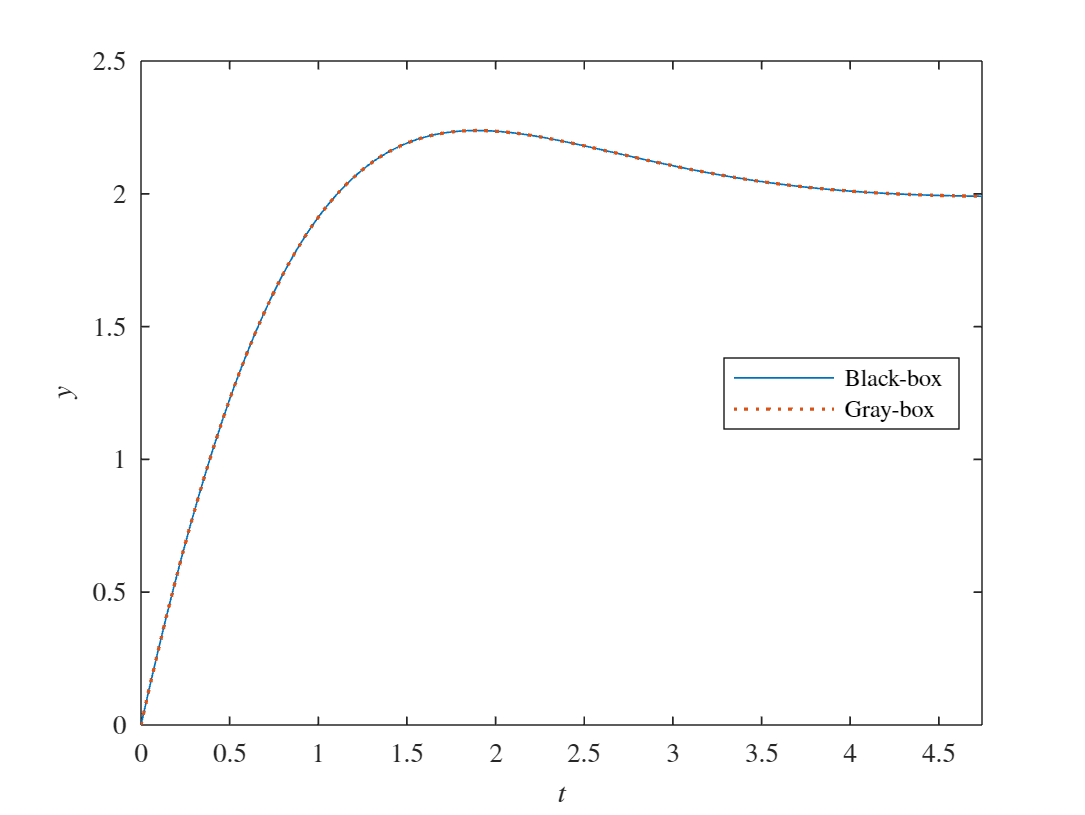


figure
hold on
[y,t] = step(blackbox);
plot(t, y, '-', 'DisplayName','Black-box', 'LineWidth',0.5)
[y,t] = step(sol.sys);
plot(t, y, ':', 'DisplayName','Gray-box',  'LineWidth',1)
legend('Location','best')
xlabel('$t$')
ylabel('$y$')
xlim([min(t) max(t)])
box on